mixed0=imread('mixed_lowQuality.png')

mixed0 = 747×994×3 uint8 array
mixed0(:,:,1) =

    28    28    27    27    27    27    27    27    27    27    27    27    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    26    

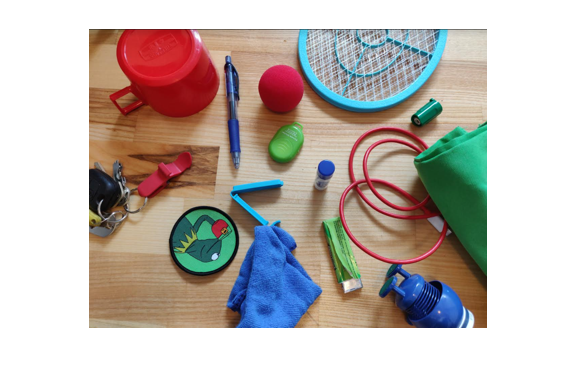

mixed = imresize(mixed0,0.4);
figure
subplot(111)
imshow(mixed)

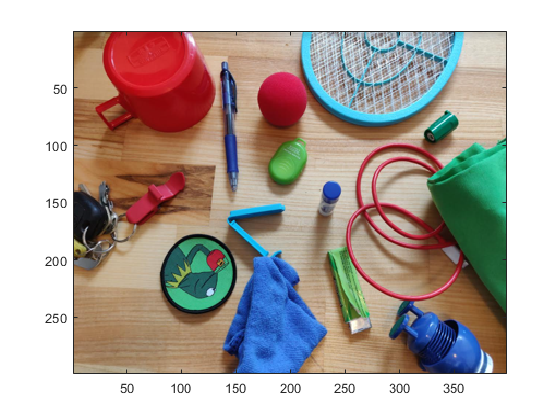

figure
mixed_scaled = imagesc(mixed,[0 255]);

 [x_pixels,y_pixels,Colors] = size(mixed)

x_pixels =    299


y_pixels =    398


Colors =      3


whos l

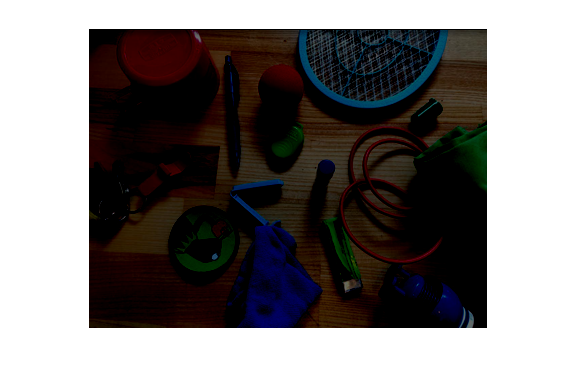

mixed_sub = imsubtract(mixed,150);
figure
imshow(mixed_sub)

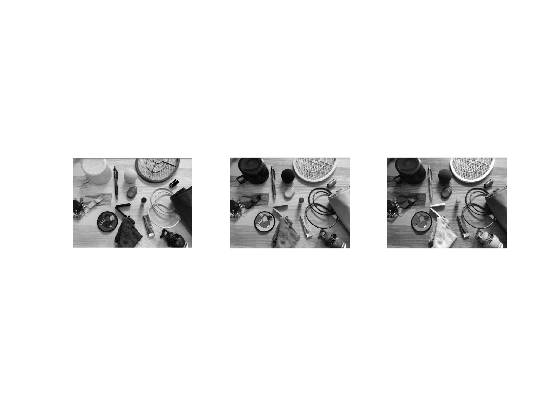

redChannel = mixed(:, :, 1);
greenChannel = mixed(:, :, 2);
blueChannel = mixed(:, :, 3);

figure
hold on
subplot(131)
imshow(redChannel)
subplot(132)
imshow(greenChannel)
subplot(133)
imshow(blueChannel)
hold off

sudukoBW=imread('suduko_mellem.png');
imfinfo 'suduko_white.png'

ans = struct with fields:
                  Filename: 'C:\Users\jacob\Desktop\ADSB_Projekt\statisk billede\suduko_white.png'
               FileModDate: '29-Sep-2021 18:46:40'
                  FileSize: 1645
                    Format: 'png'
             FormatVersion: []
                     Width: 395
                    Height: 393
                  BitDepth: 24
                 ColorType: 'truecolor'
           FormatSignature: [137 80 78 71 13 10 26 10]
                  Colormap: []
                 Histogram: []
             InterlaceType: 'none'
              Transparency: 'none'
    SimpleTransparencyData: []
           BackgroundColor: []
           RenderingIntent: 'perceptual'
            Chromaticities: [0.3127 0.329 0.64 0.33 0.3 0.6 0.15 0.06]
                     Gamma: 0.45455
               XResolution: 3779
               YResolution: 3779
            ResolutionUnit: 'meter'
                   XOffset: []
                   YOffset: []
                OffsetUnit: []

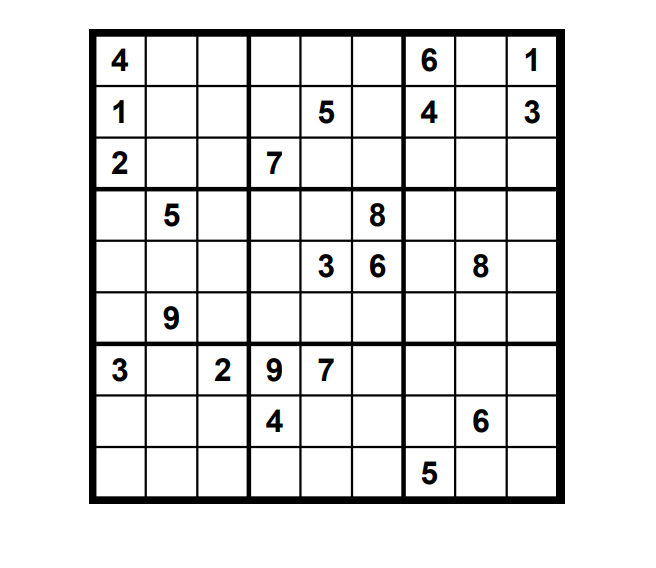

%sudukoBW=imresize(sudukoBW,1.5);
figure
imshow(sudukoBW)

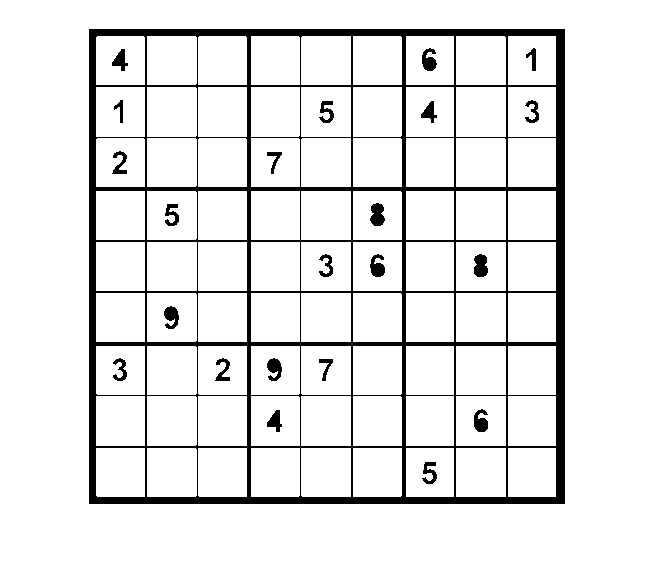

   data = sudukoBW;
    imChange1 = rgb2gray(data);
    %imChange2 = medfilt2(imChange1, [1 1]);
    imChange3 = imbinarize(imChange1,0.18); %0.18 normalt (0.07 ved grøn)  (im2bw)
    imChange4 = bwareaopen(imChange3,100); %300
    bw = bwlabel(imChange4, 8);
    felt_data = regionprops(bw, 'BoundingBox', 'Centroid');
    
    figure
    imshow(bw);

    imagesc(data);
    
    hold on
    
    pos_data = []


pos_data =

     []



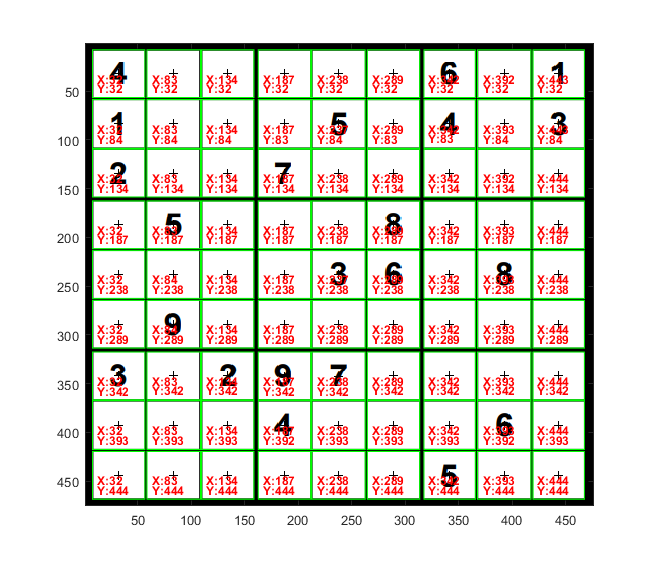

    for object = 1:length(felt_data)
        bb = felt_data(object).BoundingBox;
        bc = felt_data(object).Centroid;
        
        pos_data = [bc];
        rectangle('Position',bb,'EdgeColor','g','LineWidth',0.8)
        plot(bc(1),bc(2), '-black+')
       
        textX=text(bc(1)-20,bc(2)+5, strcat('X:', num2str(round(bc(1)))));
        textY=text(bc(1)-20,bc(2)+15, strcat('Y:', num2str(round(bc(2)))));
        set(textX, 'FontName', 'Arial', 'FontWeight', 'bold', 'FontSize', 9, 'Color', 'red');
        set(textY, 'FontName', 'Arial', 'FontWeight', 'bold', 'FontSize', 9, 'Color', 'red');
    end
    hold off

 pos_data

pos_data =         443.5          444


 format short G
 felt_data

felt_data = 81×1 struct array with fields:
    Centroid
    BoundingBox


x_center =[];
y_center =[];
 for i = 0:length(felt_data)-1
     find_x=felt_data(1+i).Centroid(1);
     x_center = [x_center,find_x];
     find_y=felt_data(1+i).Centroid(2);
     y_center = [y_center,find_y];
 end
 
 x_center
y_center
%koordinater på boksene - X og Y på venstre top hjørne og højre nedre
%hjørne 

x_box_topLeft=[];
y_box_topLeft=[];

x_box_botRight=[];
y_box_botRight=[];
for i = 0:length(felt_data)-1
     find_x1=felt_data(1+i).BoundingBox(1);
     x_box_topLeft = [x_box_topLeft,find_x1];
     
     find_y1=felt_data(1+i).BoundingBox(2);
     y_box_topLeft = [y_box_topLeft,find_y1];
     
     
     
     find_x2=felt_data(1+i).BoundingBox(3);
     x_box_botRight = [x_box_botRight,(find_x2+find_x1)];
     
     find_y2=felt_data(1+i).BoundingBox(4);
     y_box_botRight = [y_box_botRight,(find_y2+find_y1)]; 
     
     
 end
 x_box_topLeft
 
 y_box_topLeft
 
 x_box_botRight
y_box_botRight

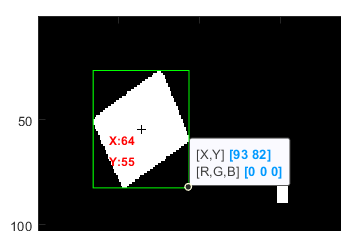

34.5+59 = modsatte hjørne kordinat X

26.5+56 = modsatte hjørnekordinat Y

  
    %opdater figur ved hvert loop:
    %drawnow;